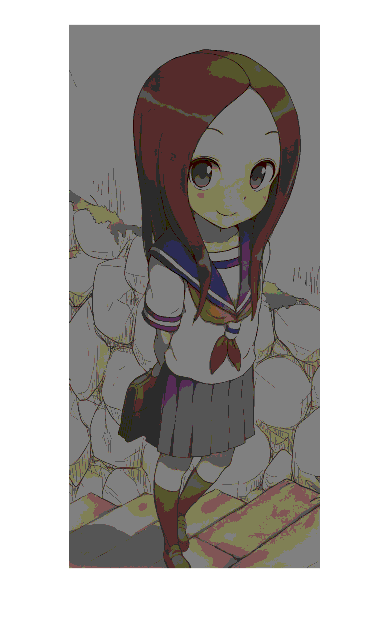

%全彩显示代码
clear;
N = 9;   %n^2
n = sqrt(N);
a=0.5;
img=imread("C:\Users\De'l'l\Desktop\bnu(1).png");
IC = double(img);
% IR = double(img(:,:,1));
% IG = double(img(:,:,2));
% IB = double(img(:,:,3));
I = max(max(sum(IC,3)));
% NR = round(IR./I*N);
% NG = round(IG./I*N);
% NB = round(IB./I*N);
NC = round(IC/I*N);

% Img(:,:,1) = NR./N*I/255*a;
% Img(:,:,2) = NG./N*I/255*a;
% Img(:,:,3) = NB./N*I/255*a;
Img = NC./N*I/255*a;
imshow(Img)

imwrite(Img,'img.png','png')

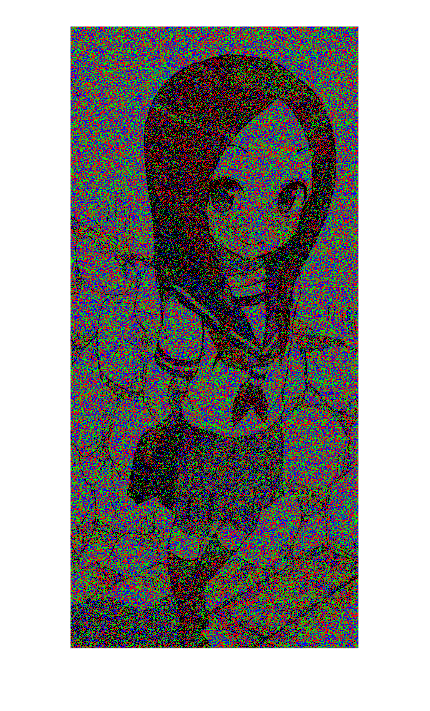

Img_color = zeros(size(IC,[1,2])*n);  %结构类型存储
for i = 1:size(IC,1)
    for j = 1:size(IC,2)
        array = 0:N-1;
        shuffled_array = array(randperm(length(array)));
        for k=1:3
            index = shuffled_array(1:NC(i,j,k));
            shuffled_array = shuffled_array(NC(i,j,k)+1:length(shuffled_array));
            for ind=index
                Img_color(n*(i-1)+mod(ind,n)+1, n*(j-1)+floor(ind/n)+1 ) = k;
            end
        end
    end
end
Img = zeros([size(IC,[1,2])*n,3]);
Img(:,:,1) = (Img_color==1); %将全彩图拆分为RGB通道
Img(:,:,2) = (Img_color==2);
Img(:,:,3) = (Img_color==3);
imshow(Img)


imwrite(Img,'img2.png','png')

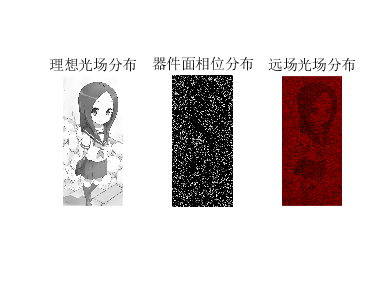

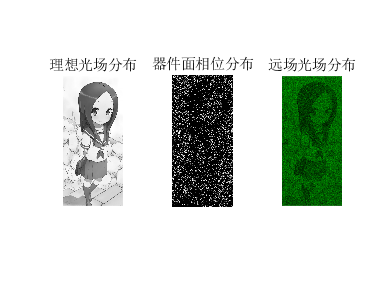

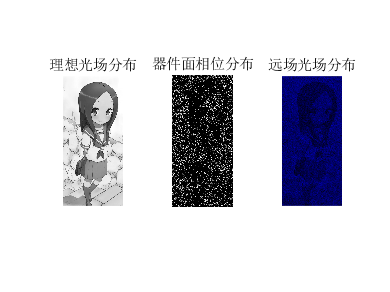

maxn = 50;% 设置迭代次数
% Hol_img(:,:,:,1) = imread("C:\Users\De'l'l\Desktop\pic_R.png");
% Hol_img(:,:,:,2) = imread("C:\Users\De'l'l\Desktop\pic_B.png");
% Hol_img(:,:,:,3) = imread("C:\Users\De'l'l\Desktop\pic_G.png");
Hol_img = imread("C:\Users\De'l'l\Desktop\bnu(1).png");

Comb_img = zeros([size(Img_color),3]);
Comb_hologram = zeros([size(Img_color)]);

for k=1:3
    figure;
    subplot(131)
%     Im = rgb2gray(Hol_img(:,:,:,k));
%     Im = double(Im);
    Im = Hol_img(:,:,k);
    Im = double(Im);
    Im = imresize(Im,size(Img_color),'bilinear');
    im_original = Im./max(max(Im));
    %im_original = 1 - im_original;
    
    imshow(im_original,[]);
    title('理想光场分布');
    
    % im_hologram表示全息面的图像，im_image表示成像面图像
    im_image = im_original.*exp(2i*pi*rand(size(im_original)));% 加入随机相位
    for n = 1:maxn % 迭代到指定次数结束
    % 反向传播计算全息图
    im_hologram = ifft2(ifftshift(im_original.*exp(1i*angle(im_image))));
    % 取全息图相位，振幅全部置一，模拟正向传播，计算像面图像
    im_image = fftshift(fft2(Img(:,:,k).*exp(1i*angle(im_hologram))));
    end
    angle_hologram = Img(:,:,k).*angle(im_hologram);
    angle_hologram = mod(angle_hologram,2*pi);
    % 相位全息图显示
    subplot(132)
    imshow(angle_hologram,[0,2*pi]);
    %img255=uint8((angle_hologram+pi)/2/pi*255);
    %imwrite(img255,'D:\far_smile.png');
    title('器件面相位分布');
    
    % 光场归一化
    im_field = abs(fftshift(fft2(Img(:,:,k).*exp(1i*angle(im_hologram)))));
    im_field = (im_field -min(min(im_field)))./(max(max(im_field)) - min(min(im_field)));
    % 全息像显示
    subplot(133)
    Himg = zeros([size(im_field),3]);
    Himg(:,:,k) = im_field;
    imshow(Himg);
    title('远场光场分布');
    Comb_img(:,:,k) = im_field; %将三通道全息图的还原像组合
    Comb_hologram = Comb_hologram + angle_hologram; %将三通道全息图组合
end

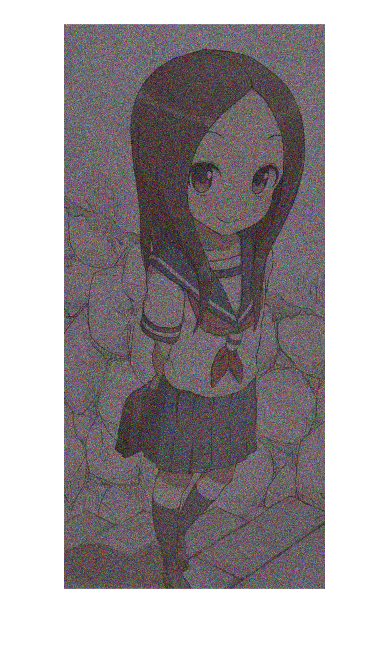


figure;
imshow(Comb_img);

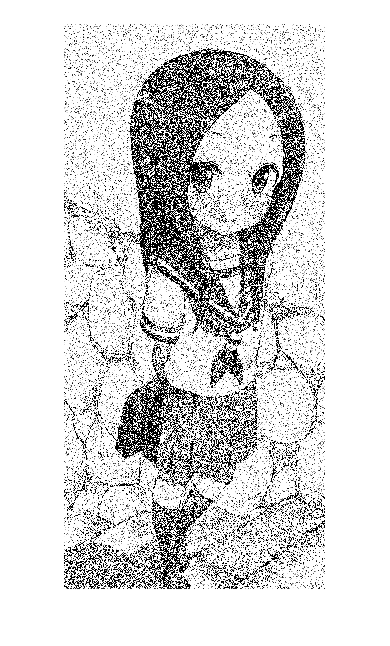

figure;
Comb_hologram = mod(Comb_hologram,2*pi); %几何相位存储
imshow(Comb_hologram);


% [file1,path1]=uigetfile("C:\Users\De'l'l\Desktop\bnu.png",'选择图片');%取原图
% r1=imread([path1,file1]);
% [file2,path2] = uigetfile("C:\Users\De'l'l\Desktop\img2.png",'选择图片');%取比较图
% r2=imread([path2,file2]);
% r1 = mat2gray(r1);
% r2 = mat2gray(r2);
%  
% x=0:1:255;
%  
% R1 = r1(:,:,1);%原图的通道分离
% G1 = r1(:,:,2);  
% B1 = r1(:,:,3);
% H_R1=imhist(R1);%对原图的每个通道计算直方图
% H_G1=imhist(G1);
% H_B1=imhist(B1);
%  
% R2 = r2(:,:,1);  %比较图的通道分离
% G2 = r2(:,:,2);  
% B2 = r2(:,:,3);  
% H_R2=imhist(R2);% 对比较图的每个通道计算直方图
% H_G2=imhist(G2);
% H_B2=imhist(B2);
% 
% t1=0;n1=0;m1=0;%赋初始值
% t2=0;n2=0;m2=0;
% t3=0;n3=0;m3=0;
% for i=1:length(H_R1)
%     y1=[];                %对R通道的算法分析
%     if H_R1(i)~=H_R2(i)
%         y1=min([H_R1(i),H_R2(i)]);
%     else
%         y1=H_R1(i);
%     end
%     L1(i)=y1;
%     t1=t1+L1(i);
%     n1=n1+H_R1(i);
%     m1=m1+H_R2(i);
%     
%      y2=[];                %对G通道的算法分析
%     if H_G1(i)~=H_G2(i)
%         y2=min([H_G1(i),H_G2(i)]);
%     else
%         y2=H_G1(i);
%     end
%     L2(i)=y2;
%     t2=t2+L2(i);
%     n2=n2+H_G1(i);
%     m2=m2+H_G2(i);
%     
%     y3=[];                %对B通道的算法分析
%     if H_B1(i)~=H_B2(i)
%         y3=min([H_B1(i),H_B2(i)]);
%     else
%         y3=H_B1(i);
%     end
%     L3(i)=y3;
%     t3=t3+L2(i);
%     n3=n3+H_B1(i);
%     m3=m3+H_B2(i);
%     
% end
% s1=min([n1,m1]);
% fin1=(t1/s1);%R通道的相似度
%  
% s2=min([n2,m2]);
% fin2=(t2/s2);%G通道的相似度
%  
% s3=min([n3,m3]);
% fin3=(t3/s3);%B通道的相似度
%  
% fin=mean([fin1,fin2,fin3])%最终的图像相似度
% 
%  
% subplot(231);imshow(r1);title('原图');
% subplot(232);imshow(r2);title('比较图');
% subplot(233);text(0.5,.5,{'相似度为',num2str(fin)},'FontSize',24,'HorizontalAlignment','center');
% subplot(234);plot(x,H_R1,'b',x,H_R2,'r:');title('R直方图比较');legend('原图','比较图');
% subplot(235);plot(x,H_G1,'b',x,H_G2,'r:');title('G直方图比较');legend('原图','比较图');
% subplot(236);plot(x,H_B1,'b',x,H_B2,'r:');title('B直方图比较');legend('原图','比较图');
%  